# Tarea 1: Coeficientes de la serie de Fourier

### Autores: Maria Fernanda Palacio, Sebastián Suárez y Estefania Laverde

#### Universidad del Rosario

#### Escuela de Ingenieria, Ciencia y Tecnología

## Introducción

El trabajo expuesto se plantea como una solución al problema de envío de una señal, específicamente de la información de un color con el cual los profesionales de Flora y Fauna necesitan trabajar, en una situación con limitantes de ancho de banda. 

Para ello, en base a un color en formato RGB, se encuentran los coeficientes de la Serie de Fourier del color traducido a binario, y posteriormente se reconstruye en base a dichos coeficientes.

A continuación se encuentra el código con el cual fue posible solucionar el problema.

## Procedimiento

El primer paso para encontrar los coeficientes del color, es hayar la función que describe la señal en binario de manera manual. El codigo RGB que se usó es (18, 163, 155), y para trasformarlo a binario simplemente se pasó cada uno de los números a binario y luego se concatenó, obteniendo así la señal 000100101010001110011011. En base en ella se construyó la función expuesta en la línea 19-32.

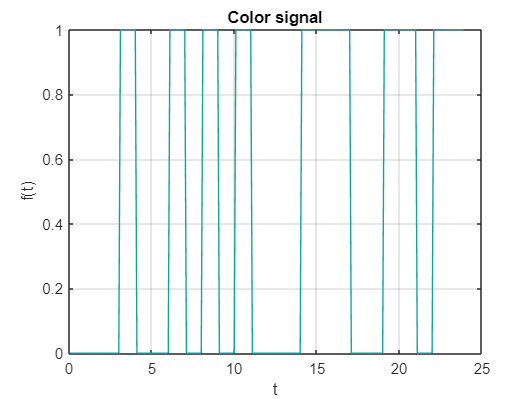


%Inicializacion del codigo
clear all, close all, clc

%Variables iniciales

T = 24;          %segundos
Ts = 0.1;        %segundos/muestra
t = 0:Ts:T-Ts;   %vector tiempo de muestreo

%Color en RGB:

% R = 18 = 00010010
% G = 163 = 10100011
% B = 155 = 10011011

%Funcion del color binario

f((t>0)&t<=3)=0;
f((t>3)&(t<=4))=1;
f((t>4)&(t<=6))=0;
f((t>6)&(t<=7))=1;
f((t>7)&(t<=8))=0;
f((t>8)&(t<=9))=1;
f((t>9)&(t<=10))=0;
f((t>10)&(t<=11))=1;
f((t>11)&(t<=14))=0;
f((t>14)&(t<=17))=1;
f((t>17)&(t<=19))=0;
f((t>19)&(t<=21))=1;
f((t>21)&(t<=22))=0;
f((t>22)&(t<=24))=1;

%Grafica de la funcion
plot(t,f,'Color','#12a39b')
grid on
title('Color signal')
xlabel('t'), ylabel('f(t)')

Una vez obtenida la función, se procedió a calcular los coeficientes de la Serie de Fourier, teniendo en cuenta que para un número $N$ de armónicos, los coeficientes están dados por


$$a_n = \frac{2T_s}{T}\sum_t f(t)cos(\frac{2\pi t n}{T})$$



$$b_n = \frac{2T_s}{T}\sum_t f(t)sin(\frac{2\pi t n}{T})$$


Teniendo en cuenta que $T$ es el periodo de la señal, $T_s$ son los segundos de muestreo,  y que se convierte en una sumatoria en vez de una integral por el hecho de que la función ya está evaluada en unos valores del tiempo. Note que estos coeficientes separan la integral original en la parte real e imaginaria para trabajarla más comodamente.

Luego de contar con los coeficientes, se visualizan en la gráfica expuesta enseguida.

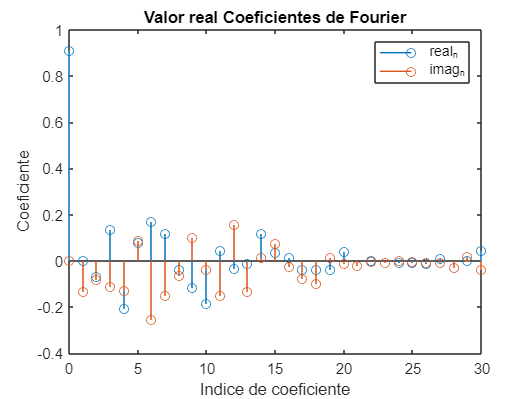


%Calculo de coeficientes de Fourier
N = 30; 
realc = zeros(1,N+1);
imagc = zeros(1,N+1);

for n=0:N
    cosTerm = cos(2*pi*t*n/T);
    sinTerm = sin(2*pi*t*n/T);
    
    realc(n+1) = (2*Ts/T)*sum(f.*cosTerm);
    imagc(n+1) = (2*Ts/T)*sum(f.*sinTerm);
end

%Visualizar coeficientes 

stem(0:N, realc)
hold on
stem(0:N, imagc)
hold off
xlabel('Indice de coeficiente')
ylabel('Coeficiente')
legend('real_n','imag_n')
title('Valor real Coeficientes de Fourier')

Contando con los coeficientes, se procede a reconstruir la señal del color, lo cual se hace de manera sencilla teniendo en cuenta que la representación de la Serie de Fourier con los coeficientes obtenidos es 


$$f_r(t) = \frac{a_0}{2}+\sum_{n=0}^{N}(a_ncos(\frac{2\pi nt}{T})+b_nsin(\frac{2\pi nt}{T}))$$


Y luego, se grafica la reconstrucción.

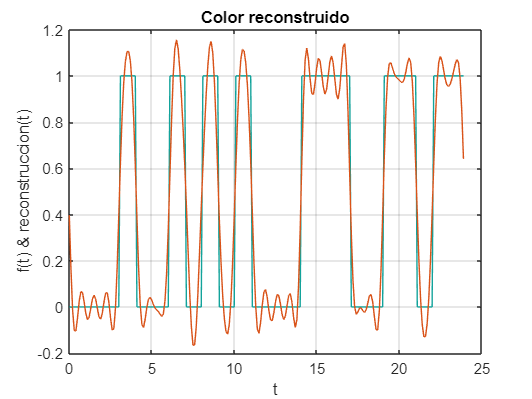

%Reconstruccion de la señal
f_reconstruida = (realc(1)/2)*ones(size(t));

for n=1:N
   cosTerm = cos(2*pi*t*n/T);
   sinTerm = sin(2*pi*t*n/T); 

   f_reconstruida = f_reconstruida + realc(n+1)*cosTerm + imagc(n+1)*sinTerm; 
end

plot(t,f,'Color','#12a39b')
hold on
plot(t,f_reconstruida)
hold off
grid on
title('Color reconstruido');
xlabel('t');
ylabel('f(t) & reconstruccion(t)')

%Calculo del error
errorN = f-f_reconstruida

errorN =    -0.3973   -0.1633    0.0134    0.1023    0.1031    0.0456   -0.0245   -0.0665   -0.0619   -0.0206    0.0283    0.0548    0.0446    0.0066   -0.0340   -0.0512   -0.0343    0.0057    0.0431    0.0528    0.0268   -0.0206   -0.0595   -0.0621   -0.0199    0.0476    0.1001    0.0942    0.0034   -0.1694   -0.3938    0.3744    0.1745    0.0283   -0.0618   -0.1044   -0.1064   -0.0656    0.0274    0.1796    0.3836   -0.3868   -0.1714   -0.0094    0.0765    0.0889    0.0527    0.0026   -0.0329   -0.0418


Para la segunda parte del trabajo, se cuenta con los coeficientes de la señal del grupo conformado por (NOMBRES :(( ) y se requiere reconstruir la señal. Para ello, se hace uso del mismo código expuesto anteriormente y a continuación se muestran los resultados.


%Parte dos: reconstrucción del color de otro grupo.


Con la grafica de la señal es sencillo observar que el código binario del color es (CODIGO BINARIO), y por lo tanto el RGB será (RGB)